[cbAudio1, cbFs1] = audioread('common_blackbird.wav');
% convert cbAudio to mono
cbAudio1 = sum(cbAudio1, 2) / size(cbAudio1, 2);
[cbAudio2, cbFs2] = audioread('common_blackbird_2.wav');
cbAudio2 = sum(cbAudio2, 2) / size(cbAudio2, 2);

sound(cbAudio1,cbFs1)

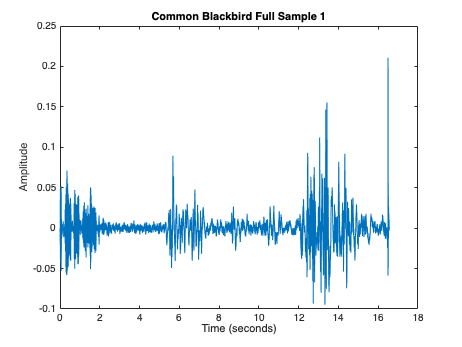

plot((0:numel(cbAudio1)-1)/cbFs,cbAudio1)
title('Common Blackbird Full Sample 1')
xlabel('Time (seconds)')
ylabel('Amplitude')

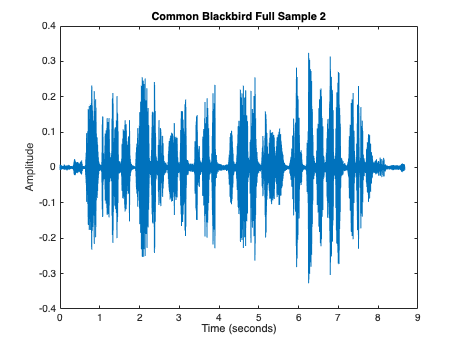

plot((0:numel(cbAudio2)-1)/cbFs2,cbAudio2)
title('Common Blackbird Full Sample 2')
xlabel('Time (seconds)')
ylabel('Amplitude')

cb1 = cbAudio1(1:1+2*cbFs1);
cb2 = cbAudio2(1:1+2*cbFs2);

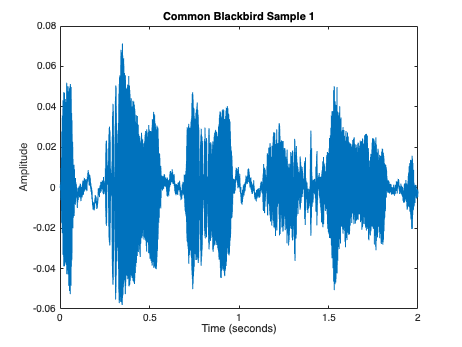

plot((0:numel(cb1)-1)/cbFs1,cb1)
title('Common Blackbird Sample 1')
xlabel('Time (seconds)')
ylabel('Amplitude')

sound(cb1,cbFs1);

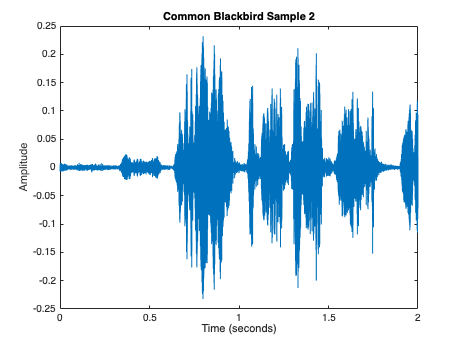

plot((0:numel(cb2)-1)/cbFs2,cb2)
title('Common Blackbird Sample 2')
xlabel('Time (seconds)')
ylabel('Amplitude')

sound(cb2,cbFs2);

gammaFiltBank = gammatoneFilterBank([50 20000],64,cbFs1);

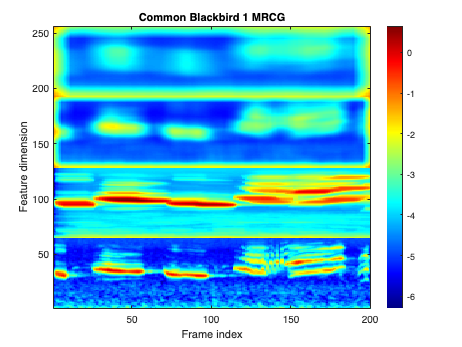

cbAudioOut1 = gammaFiltBank(cb1);
cbMrcgFeatures1 = mrcg(cbAudioOut1, cbFs1);
imagesc(cbMrcgFeatures1)
colormap jet
colorbar
ylabel('Feature dimension')
xlabel('Frame index')
title('Common Blackbird 1 MRCG')
set(gca,'YDir','normal')

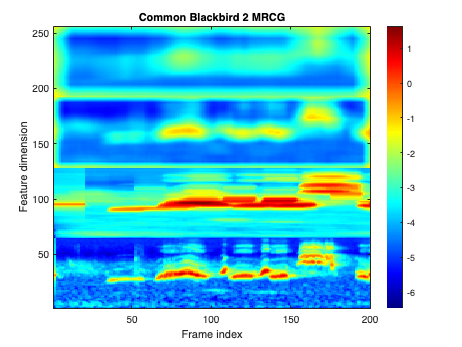

cbAudioOut2 = gammaFiltBank(cb2);
cbMrcgFeatures2 = mrcg(cbAudioOut2, cbFs2);
imagesc(cbMrcgFeatures2)
colormap jet
colorbar
ylabel('Feature dimension')
xlabel('Frame index')
title('Common Blackbird 2 MRCG')
set(gca,'YDir','normal')

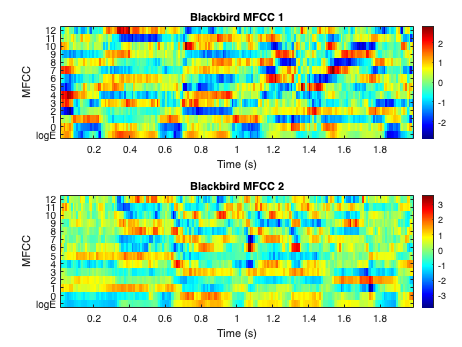

tiledlayout(2,1);

nexttile
mfcc(cb1,cbFs1)
title('Blackbird MFCC 1')

nexttile
mfcc(cb2,cbFs2)
title('Blackbird MFCC 2')